
I1 = imread("stereo-pairs\p21.jpg");
I2 = imread("stereo-pairs\p22.jpg");
I11 = rgb2gray(I1);
I12 = rgb2gray(I2);

[matchedLeft, matchedRight] = SurfFeaturepoints(I11,I12);
[F,inliersIndex] = estimateFundamentalMatrix(matchedLeft.Location, ...
    matchedRight.Location,"Method","RANSAC");
F

F =     0.0000    0.0000   -0.0048
   -0.0000   -0.0000   -0.0670
    0.0023    0.0651    0.9956


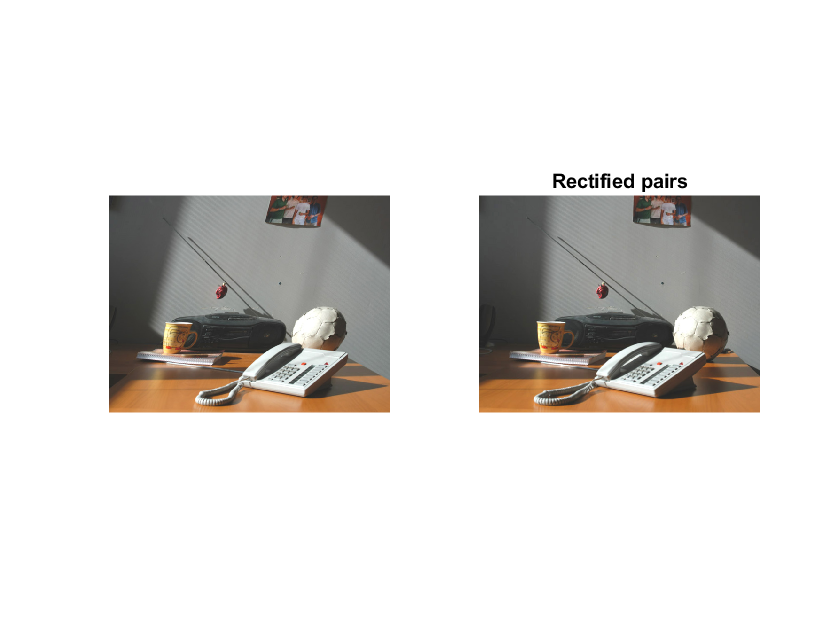


% rectify
inlier1 = matchedLeft.Location(inliersIndex,:);
inlier2 = matchedRight.Location(inliersIndex,:);
[t1, t2] = estimateUncalibratedRectification(F,inlier1,...
    inlier2,size(I1));
[I1Rect,I2Rect] = rectifyStereoImages(I1,I2,t1,t2);

subplot(121)
imshow(I1Rect)
subplot(122)
imshow(I2Rect)
title('Rectified pairs')

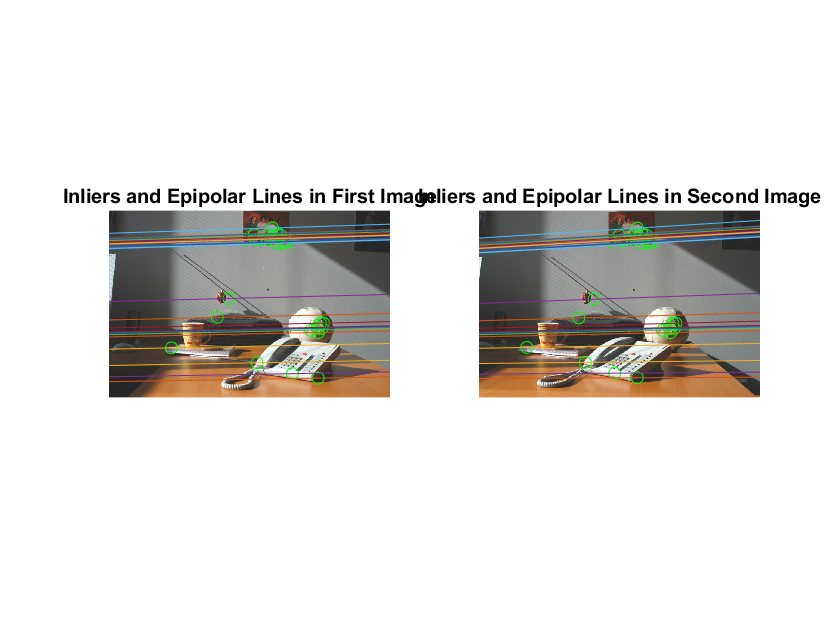


draw_epipolar_lines(I1,I2,F,inlier1,inlier2)

disparity map

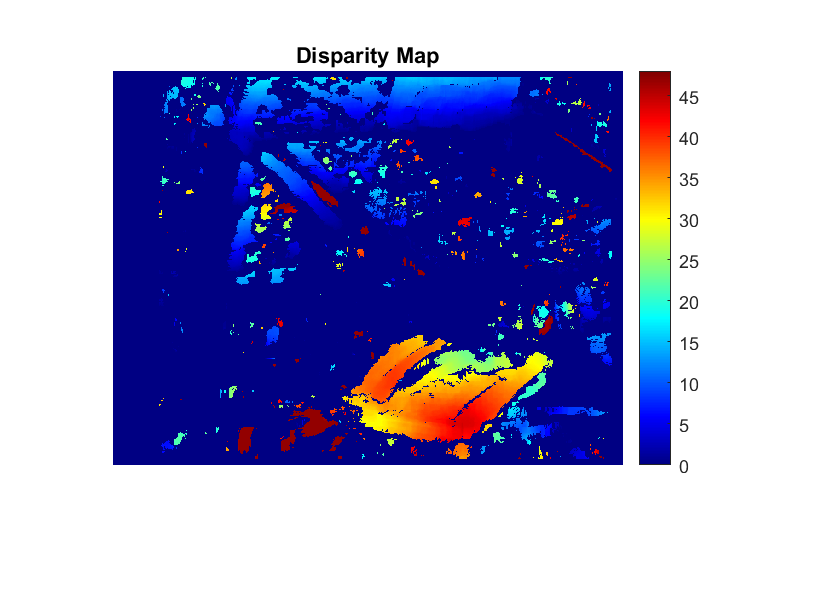

disparityRange = [0 48];
disparityMap = disparityBM(rgb2gray(I1Rect),rgb2gray(I2Rect), ...
    'DisparityRange',disparityRange);

figure
imshow(disparityMap,disparityRange)
title('Disparity Map')
colormap jet
colorbar